# Decoding vision using machine learning approaches

There is a close relationship between machine learning, AI, and systems neuroscience that is often under appreciated (including by neuroscientists). Here I am going to walk through one of the most straightforward, but effective, uses of machine learning for understanding what is going on in the brain:** using non-linear regression to relate neural signals to visual stimuli. **As you will see, even a relatively simple ML technique is extremely powerful in 'reading out' neural signals, and doing this can be as accurate as simply asking a subject what they saw.

All codes and data used in this project are available on my [github](http://www.github.com/jmohl/neural_ml_example).

## Vision through neurons

Everything you see is the result of neurons in your brain responding to some visual stimulus. Typically, these 'responses' take the form of action potentials or 'spikes', and we can record these spikes using an electrode inserted into the brain. If we record spikes from a single neuron while we show many different types of visual stimulus, we find that some stimuli will generate a lot of spiking activity while others will not. This allows us to find the relationship between the spiking activity of some recorded neuron and the visual stimulus. Once we know this relationship, we can use a tool like **regression** to go the other direction: take the spiking activity and predict the visual stimulus that is being shown.

For a straightforward example, lets imagine that you are recording a neuron while flashing lights at 4 different locations (here, a negative location means to the left and a positive location means to the right). If you repeat this experiment 10 times for each location, you might get a set of spike counts that looks like the red dots below. There is a lot of noise in the signal (neurons, like many things, have variability that cannot easily be predicted), but there is a clear trend in average spike count as the target location changes. This neuron appears to have a fairly linear relationship between location and spike count. You can use this linear relationship to predict the spike count in between the conditions you tested (a target at the +10 location would be expected to generate around 15 spikes, for instance).

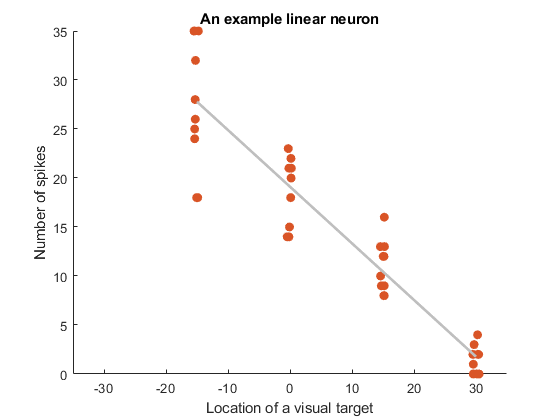

%% some formatting options
neuron_colors =[.85 .33 0.15;.07 .56 0.73; .52,.66,.55];
default_lw = 2;
% making a few example neurons
n_neurons = 3;
n_trials = 10;
lambdas = [30,20,10,1;5 50 25 5;10 45 60 40]; %mean firing rates for different conditions
cell1 = zeros(1,n_trials*length(lambdas));
cell2 = cell1;
cell3 = cell1;
cond_array = zeros(1,n_trials*length(lambdas));
conds = [-15,0,15,30];
for i = 1:length(lambdas)
    cell1((i-1)*n_trials+1:i*n_trials) = poissrnd(lambdas(1,i),1,n_trials);
    cell2((i-1)*n_trials+1:i*n_trials) = poissrnd(lambdas(2,i),1,n_trials);
    cell3((i-1)*n_trials+1:i*n_trials) = poissrnd(lambdas(3,i),1,n_trials);
    cond_array((i-1)*n_trials+1:i*n_trials) = ones(1,n_trials)*conds(i);
end
neuron_array = [cell1;cell2;cell3];

% a simple linear neuron
figure
scatter(cond_array,cell1,'jitter','on', 'jitterAmount',0.5,'MarkerFaceColor',neuron_colors(1,:),'MarkerEdgeColor',neuron_colors(1,:))
reg_line = lsline;
reg_line.LineWidth = default_lw; 
ylabel('Number of spikes')
xlabel('Location of a visual target')
title('An example linear neuron')
xlim([-35 35])

Sometimes neurons have this type of linear relationship, but more commonly they have a more complicated response function. This is often true in other kinds of data, as very few things are truly linearly related. **Understanding this relationship between the predictors and your variables of interest is the key to non-linear regression**

 In many neurons, a very common response function is gaussian tuning. All this means is that there is a specific location where the responses 'peak' and then the number of spikes drop off as you move in either direction, and that this pattern can be roughly described by a gaussian function. This is lucky for us because gaussian functions only have 2 free parameters, and so this only slightly increases the complexity of our model compared to a linear response function. Lets look at two more example cells which more clearly show this peaked behavior.

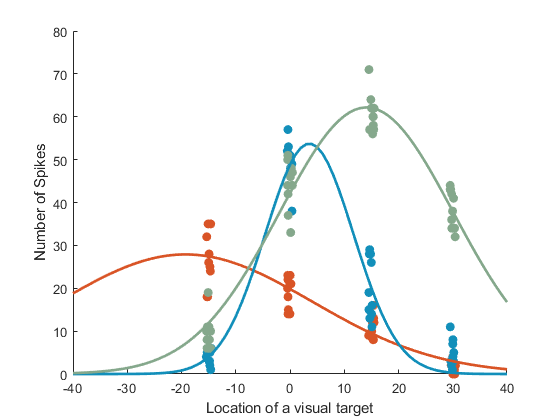

yCenter=-40:1:40; %Discrete set of positions
sFit = zeros(n_neurons,length(yCenter));
for n=1:n_neurons %Loop over all neurons
    f=fit(cond_array',neuron_array(n,:)','gauss1'); %Fit the encoding model
    sFit(n,:)=f.a1.*exp(-((yCenter-f.b1)./f.c1).^2); %Predict firing rate at every point in ycenter
end

figure
hold on
scatter(cond_array,cell1,'jitter','on', 'jitterAmount',0.5,'MarkerFaceColor',neuron_colors(1,:),'MarkerEdgeColor',neuron_colors(1,:))
scatter(cond_array,cell2,'jitter','on', 'jitterAmount',0.5,'MarkerFaceColor',neuron_colors(2,:),'MarkerEdgeColor',neuron_colors(2,:))
scatter(cond_array,cell3,'jitter','on', 'jitterAmount',0.5,'MarkerFaceColor',neuron_colors(3,:),'MarkerEdgeColor',neuron_colors(3,:))
for i = 1:n_neurons
    plot(yCenter,sFit(i,:),'Color',neuron_colors(i,:),'LineWidth',default_lw)
end
xlabel('Location of a visual target')
ylabel('Number of Spikes')

Here I am plotting two more neurons in addition to the one we had previously. These two new neurons have a clear peak in the data, with green peaking around x=15 and blue peaking around x=5. This highlights another important feature of neurons which is that they often have different relationships between spike count and location. This is critical because having different response functions allows us to resolve potentially confusing situations. For instance, if the blue neuron has a spike count around 25, which could potentially correspond with 2 target locations (x = -10 or x = +15). However, if we also have data from the red and green neurons we can resolve this ambiguity because they have different responses at the two locations in question. If we were to take that trial with 25 spikes in the blue neuron, and see that we also had 60 spikes from the green neuron and 10 spikes from the red neuron, then we would be justified in thinking that the x value was closer to +15 than -10.

And now we are getting to the real power of neurons: combining information from many neurons allows us to get very accurate guesses about target location. This is where **non-linear regression** finally enters the picture.

## Non-linear regression for decoding neural responses

Now that we know the approximate relationship between spike counts and location, we can use this information to turn it around and use it to predict what the stimulus looks like based only on the neural data. To test this we might hold out a few conditions from our training data, and then see if we could predict the locations in each of those conditions based only on the spike counts. 

I am going to use a maximum likelihood approach (really minimizing the negative log-likelihood because this is more numerically stable). Given a set of spike counts from the red, green, and blue neurons, can I predict the location that was most likely to generate this set of spikes? Let's start out with just a single condition, x=8. If I have 10 trials worth of held out data, how accurately do I predict the actual target location on those trials?

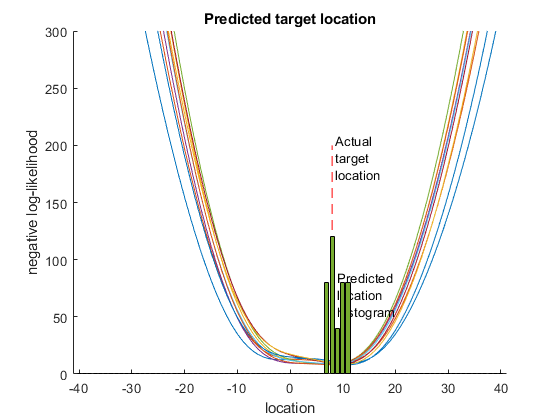

rng('default')
ex_location = 8;
n_trials = 10;
ex_pois = sFit(:,yCenter==ex_location);
predictions = zeros(1,n_trials);
figure
hold on
for i = 1:n_trials
    ex_rate = poissrnd(ex_pois); %generating spike counts for each of the neurons
    %calculate the probability of the observations under the model assuming
    %gaussian noise
    prob = poisspdf(repmat(ex_rate,1,length(yCenter)),sFit);
    probSgivenY = -sum(log(prob));
    plot(yCenter, probSgivenY)
    [~,iloc] = min(probSgivenY);
    predictions(i) = yCenter(iloc);
end
%best location
plot([ex_location, ex_location],[0,200],'r--')
text(ex_location+.5, 190,sprintf('Actual\ntarget\nlocation'))
[hc,~] = histcounts(predictions,min(yCenter)-.5:max(yCenter)+.5,'Normalization','probability');
text(ex_location+1, 70,sprintf('Predicted\nlocation\nhistogram'))

bar(yCenter,hc*400);
xlabel('location')
ylabel('negative log-likelihood')
ylim([0,300])
title(sprintf('Predicted target location'))

Here I've plotted the distribution of negative log likelihood (colored lines) for each of the 10 new trials. The lower this value, the more likely it is that the stimulus is at that location. Extracting the most likely location for each trial (green bars) shows that they cluster pretty close to the actual location. There is some variability here, which is expected (we are doing this with just 3 neurons after all!), but clearly there is a lot of predictive power here. Of course this has all been theory up to this point, so how does this work with actual neural data?

## Predicting target location from neural data

Now that we've gone through the theory, lets see how this works in practice. Here I've included a sample dataset which includes spike counts from around 9000 total trials across 73 different neurons. This includes 10 different visual target locations which span from -30 to +30 (measured in degrees, but the units don't matter here). I'm going to follow the same procedure as I did with the synthesized data. First, checking the relationship between spike count and target location it seems like gaussian response functions will be a better choice than linear again.

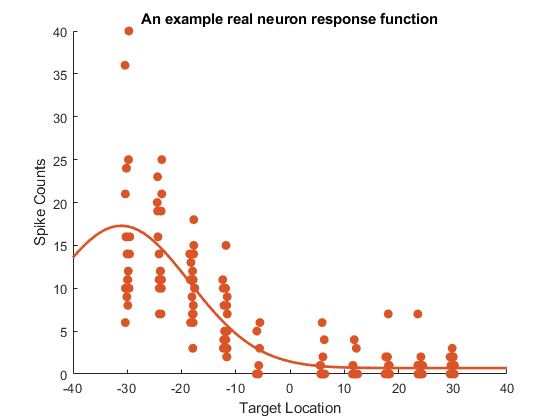

data = load('ex_neural_data.mat');
data=data.ex_neural_data;
ng = findgroups(data.file_ID);

%first look at an example neuron tuning curve
ex_cell = data(data.file_ID == 10,:);
ex_fit = gauss_pdf_1d(ex_cell.spk_ct,ex_cell.V_tar,yCenter); %note this is a slightly different fitting function, defined at the end of this document
figure
hold on
scatter(ex_cell.V_tar,ex_cell.spk_ct,'jitter','on', 'jitterAmount',0.5,'MarkerFaceColor',neuron_colors(1,:),'MarkerEdgeColor',neuron_colors(1,:))
plot(yCenter,ex_fit,'Color',neuron_colors(1,:),'LineWidth',default_lw)
ylabel('Spike Counts')
xlabel('Target Location')
title('An example real neuron response function')

Rather than synthesizing some new hypothetical data, I'm going to use a leave one out strategy to validate this model. Essentially I want to generate a bunch of 'held out' trials to test, while using the remaining data to fit the model. 

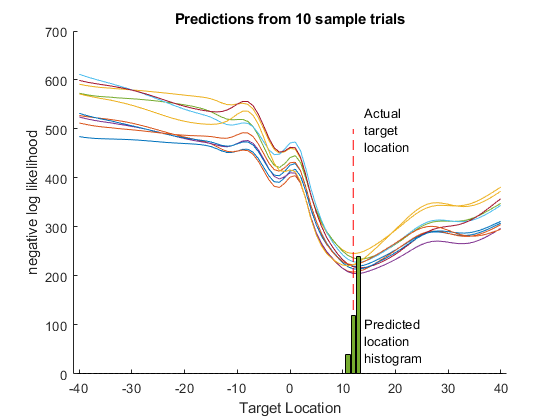

n_iterations = 10;
ex_location = 12;

data.uid = [1:height(data)]'; %adding unique ids

%going to cheat a bit here and fit the gaussians just once, to all the
%data. This is not best practice (small risk of overfitting) but for
%purposes of this demonstration is fine (and MUCH faster).
gauss_temp = @(spk_ct,tars) gauss_pdf_1d(spk_ct,tars,yCenter); %need anonymous function to include range
sfit = splitapply(gauss_temp,data(:,{'spk_ct','V_tar'}),data.file_ID); %fit gaussian tuning curve estimates for each cell, pretty slow (6 seconds JM TODO speed this up)
sfit(sfit <= 0.01) = 0.01; %minimum firing rate can't be lower than 0

%split data into train and test by holding out a single trial of a set
%condition per neuron
nll_array = zeros(n_iterations,length(yCenter));
predictions = zeros(n_iterations,1);
figure
hold on
for n=1:n_iterations
    test_data = data(data.V_tar == ex_location,:); 
    temp_sample = @(data) datasample(data,1);
    t=splitapply(temp_sample,test_data.uid,test_data.file_ID);
    test_data = data(t,:);
    
    test_mat = repmat(test_data.spk_ct,1,size(sfit,2)); %expand to match range
    likelihood = poisspdf(test_mat,sfit);
    nll = -sum(log(likelihood));
    nll_array(n,:) = nll;
    [~,iloc] = min(nll);
    predictions(n) = yCenter(iloc); %
    plot(yCenter,nll)
end
plot([ex_location, ex_location],[0,500],'r--')
text(ex_location+2, 500,sprintf('Actual\ntarget\nlocation'))
[hc,hc_bins] = histcounts(predictions,min(yCenter)-.5:max(yCenter)+.5,'Normalization','probability');
text(ex_location+2, 70,sprintf('Predicted\nlocation\nhistogram'))
bar(yCenter,hc*400);
ylabel('negative log likelihood')
xlabel('Target Location')
title('Predictions from 10 sample trials')

Just like before, I'm plotting the nll curves for 10 dfferent trials as well as the histogram of 'most likely locations' based on those nll curves. As you can see this regression is doing an excellent job of picking the correct location, as almost all of the predicted locations are within 1 degree of the actual location! This is a very good match for what the subjects are actually percieving, which I can tell because I also collected behavioral data on this task where subjects reported (by making an eye movement) where the target was located. Here I can directly compare the location predicted by the neural data with the actual responses given in the same trials. Not only is there a ton of overlap between the distributions, the neurally predicted reports are actually more precise!

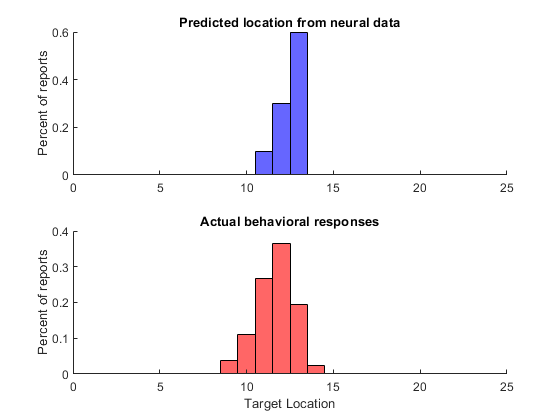

figure
subplot(2,1,1)
histogram(predictions,hc_bins,'Normalization','probability', 'FaceColor','b')
ylabel('Percent of reports')
title('Predicted location from neural data')
xlim([0,25])
box('off')

subplot(2,1,2)
histogram(test_data.resp,hc_bins,'Normalization','probability', 'FaceColor','r')
ylabel('Percent of reports')
xlabel('Target Location')
title('Actual behavioral responses')
box('off')
xlim([0,25])

## Quantifying model performance

Just looking at plots is one thing, but it would be better to quantify the model performance in a way that is more objective. The best way to do this for this kind of model is just to compute the pearson correlation between the predicted and actual locations for many trials.

n_iterations = 100;
locations = unique(data.V_tar);
predictions = zeros(n_iterations,length(locations));
responses = zeros(n_iterations,length(locations));
for i = 1:length(locations)
    location = locations(i);
    for n=1:n_iterations
        test_data = data(data.V_tar == location,:);
        temp_sample = @(data) datasample(data,1);
        t=splitapply(temp_sample,test_data.uid,test_data.file_ID);
        test_data = data(t,:);
        
        test_mat = repmat(test_data.spk_ct,1,size(sfit,2)); %expand to match range
        likelihood = poisspdf(test_mat,sfit);
        nll = -sum(log(likelihood));
        [~,iloc] = min(nll);
        predictions(n,i) = yCenter(iloc); %
        responses(n,i) = datasample(test_data.resp,1); %sample the response from a random trial
    end
end

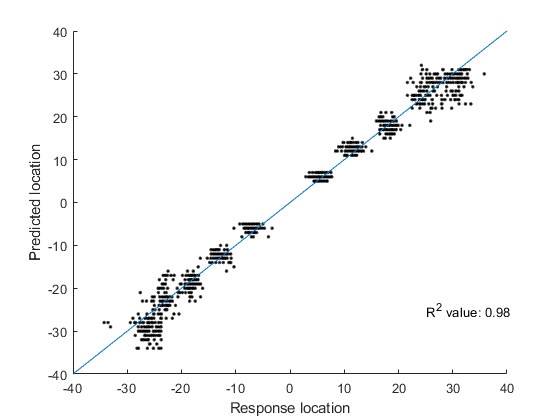

figure
hold on
plot(responses,predictions,'k.')
refline(1,0)
ylabel('Predicted location')
xlabel('Response location')
cor_mat = corrcoef(predictions,responses);
r = cor_mat(2);
r_sq = r^2;
text(25,-25,sprintf('R^2 value: %1.2f',r_sq))

An R^2 of 0.99 here essentially means that our neural data explains around 99% of the variance of our response data. This is extremely good, and indicates that we are able to essentially perfectly predict the response location based on the neural response.

## Summary and conclusions

This has mostly been a working exercise for me to ground the relationship between theory and results in my own work. All of the different pieces I've shown here (gaussian response functions, maximum likelihood regression, and leave-one-out decoding) have been well demonstrated in neuroscience, and I chose them because they offer a very straightforward story to understand how these concepts tie together. It was also easy to present this story so simply because the specific neural data I chose has a very nice and clean relationship with the parameter of interest (visual target location). Of course our brains are **much** more complicated than I have suggested here, and are capable of processing much more complicated features. Characterizing the relationships between complex features and noisy neural data is a huge field in itself, and it becoming increasingly intertwined with advanced machine learning principles([here](https://www.frontiersin.org/articles/10.3389/fncom.2016.00094/full) is a great review if you are interested in seeing the state of the art in this area). 

Still, I hope that this page has been useful for getting a preview of the utility and power of even straightforward machine learning techniques for understanding the complex inner workings of the brain. 

function sfit = gauss_pdf_1d(spk_ct,tars,range) %custom gaussian model which includes a baseline shift, to better fit real data
    fo = fitoptions('Method','NonlinearLeastSquares',...
        'Lower',[0,0,-Inf,0],...
        'Upper',[Inf,Inf,Inf,Inf],...
        'StartPoint',[1, 1, 1, 20]);
    ft = fittype('a0+a1*exp(-((x-b1)/c1)^2)','options',fo);
    f=fit(tars,spk_ct,ft); %Fit the encoding model, with a baseline added
    sfit=f.a0+f.a1.*exp(-((range-f.b1)./f.c1).^2);
end
